# Notebook 01: Project Overview

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 01**.

## 1. Understanding The Experiment and Data Acquisition Process

The data for this project was collected using an experimental design based on [Warren et al.'s 2016](https://doi.org/10.1109/JPROC.2015.2507180) study. In that study, a participant underwent the implantation of Utah Slanted Electrode Arrays in both the ulnar and median nerves of their remaining limb after an amputation procedure. 

The goal of the experiment was to design and implement a supervised machine learning algorithm to control a virtual hand. The algorithm was trained using neural activity synchronized with the intended kinematics (i.e., the change of the positions of the joints over time) of the virtual hand.

This training paradigm is called "mimic training." It relies on amputees mimicking preprogrammed movements of a prosthesis with their missing hand such that the corresponding neural signals are correlated and synchronized to the preprogrammed kinematics of the prosthesis. 

Throughout this process, the USEAs recorded neural signals from the nerves while a computer program recorded the the virtual hand's joint positions (kinematics). The researchers' goal was to decode joint kinematics from the neural signals.

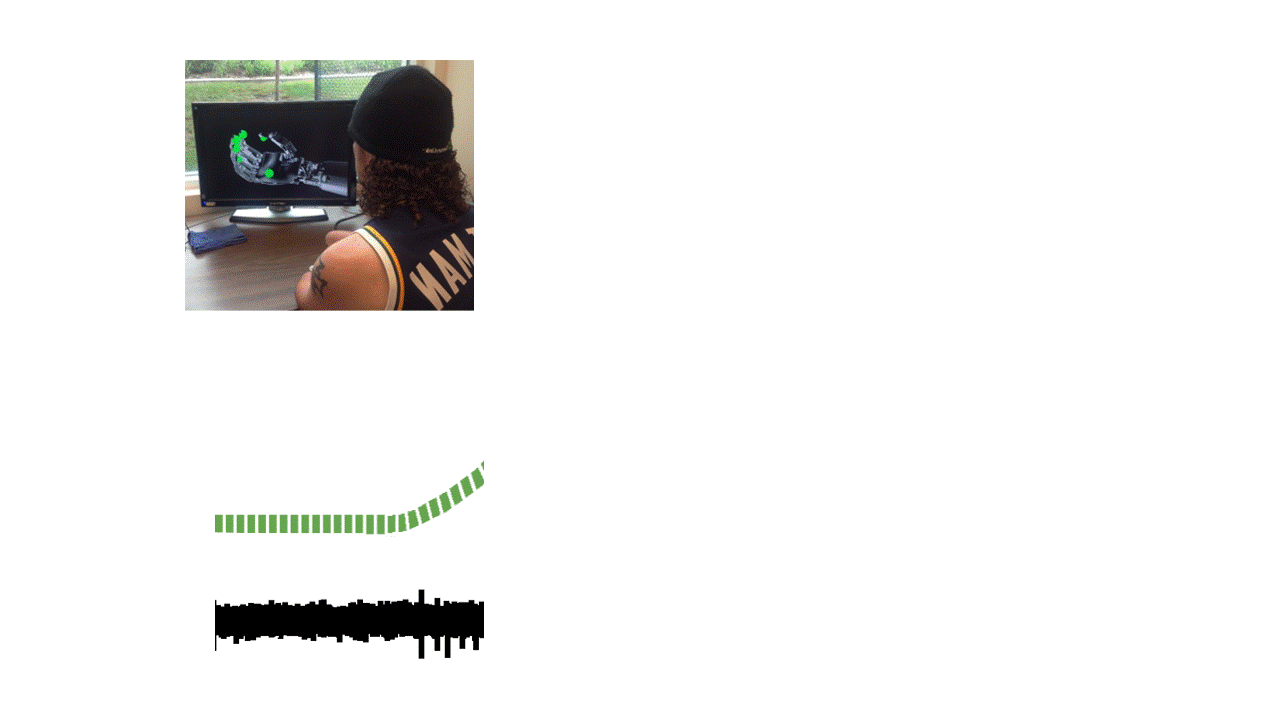

**Video Caption:** The participant stares at a virtual hand, which starts in open/relaxed state. Then, the virtual hand changes its position (as shown in the second image and the green trace), and the participant attempts to mimic the movement on the screen (as evidenced by the change in neural activity). Finally the hand goes back to rest, and the participant also stops trying to move.This results in a dataset that contains the neural activity associated with a specific type of hand motion.

## 2. Understanding The Dataset and Data Structures

cd(fileparts(matlab.desktop.editor.getActiveFilename))
clearvars
load('datasets\training_dataset.mat')
experiment_data = training_data;

The variable `experiment_data` is a [MATLAB struct](https://www.mathworks.com/help/matlab/ref/struct.html) that contains two matrices and one variable:

- `experiment_data.hand_kinematics`.- An Nx2 matrix containing the kinematic information of **two joints **of the virtual hand during the experiment. The kinematics have been normalized to a range of $[0, 1]$, where `0 = rest`** and **`1 = full flexion/pronation`. 

- `experiment_data.raw_neural_data`: An Nx6 matrix containing a **subset of six USEA channels** during the experiment.

- `experiment_data.sample_rate`.- The sample rate in $Hz$ at which both Kinematics and Neural Data were recorded.

The following code will help you visualize and understand the dataset. 

experiment_ttbl = struct_to_timetable(experiment_data)

experiment_fig = plot_timetable(experiment_ttbl);

## 3. Understanding The Research Objectives

One of the goals of this project is for you to train a Neural Network to map the values of the USEA data to the values of the hand kinematics. In other words, you will train an algorithm to decode the desired position of an artificial hand based on the current electrical activity in the patient's remaining limb. However, in their current state, the neural signals have almost no correlation to the hand kinematics, and the neural network won't be able to learn this mapping. Therefore, you will have to explore **at least two ways** to convert these neural signals into usable neural features (features that correlate better with the kinematics).

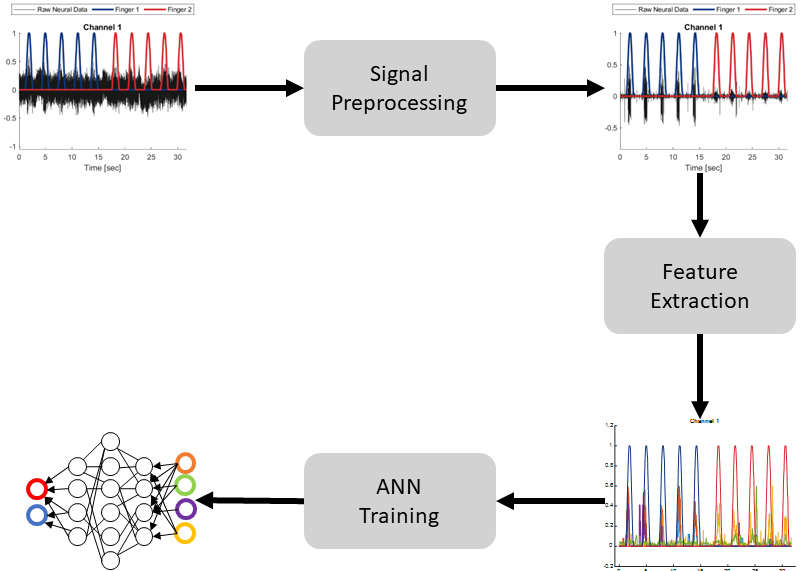

Another goal of this project is to familiarize you with spike detection and spike quality assessment. To that end, you will have to detect spikes and then determine the signal-to-noise ratio of each spike waveform for each channel. Review the SOP and rubric on the Canvas page for more information about the specific submission requirements.

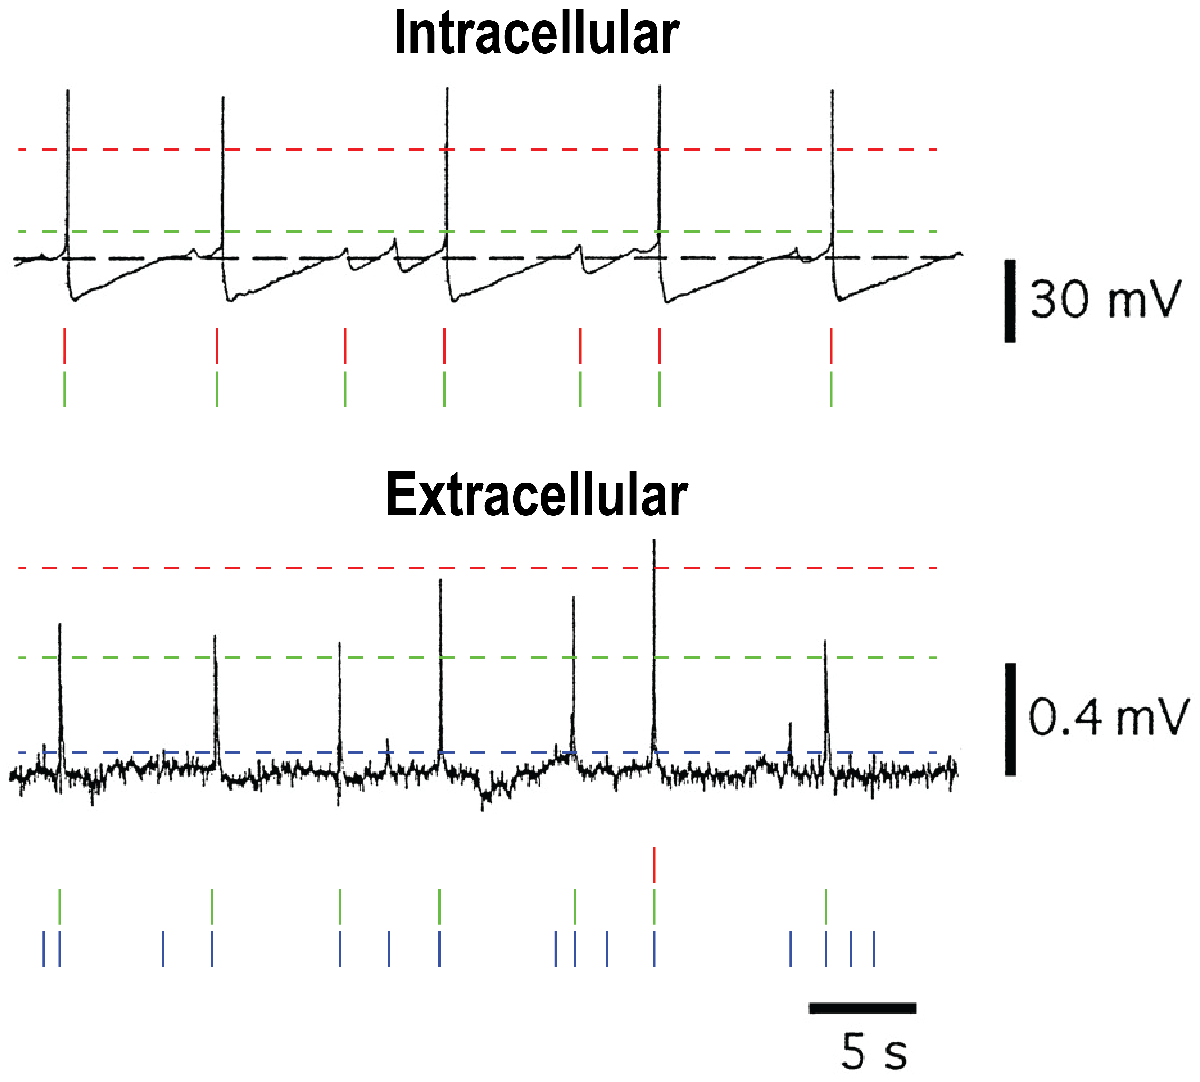

## Helper Functions

This section contains the functions used for data visualization throughout this notebook. **You do not need to change or understand the code below**, but you are welcome to do so if it helps with your project.

function ttbl = struct_to_timetable(experiment_data)
ttbl = timetable( experiment_data.hand_kinematics, experiment_data.raw_neural_data, ...
    'SampleRate', experiment_data.sample_rate, ...
    'VariableNames', ["Hand Kinematics" "Raw Neural Data"]);
end

function tlo = plot_timetable(experiment_ttbl)
tlo = tiledlayout(3,1);
nexttile
s_h = stackedplot(experiment_ttbl.Time, experiment_ttbl{:,"Hand Kinematics"}, 'LineWidth', 2, ...
    "Title", "Hand Kinematics Vs. Time", ...
    "DisplayLabels", ["Hand Position", "Wrist Position"]);
s_h.LineProperties(2).Color = "red";
nexttile([2,1])
s_h = stackedplot(experiment_ttbl.Time, experiment_ttbl{:,"Raw Neural Data"}, ...
    "Title", "Raw Neural Data Vs. Time", ...
    "DisplayLabels", ["CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"]);

experiment_ttbl = 948199×2 timetable
         Time         Hand Kinematics                              Raw Neural Data                          
    ______________    _______________    ___________________________________________________________________

    0 sec                 0    0          5.9995    -0.49995      5.9995     -9.7491      1.2499     -5.9995
    3.3333e-05 sec        0    0          3.4997      6.4994      9.4991     -5.7495      5.7495     -3.4997
    6.6667e-05 sec        0    0          4.2496     0.49995      6.2494    -0.74993      4.7496      2.9997
    0.0001 sec            0    0          6.4994      2.4998      8.2492     -4.7496     -4.9995      1.9998
    0.00013333 sec        0    0         0.99991      1.7498     0.99991     -14.249     -4.9995      2.4998
    

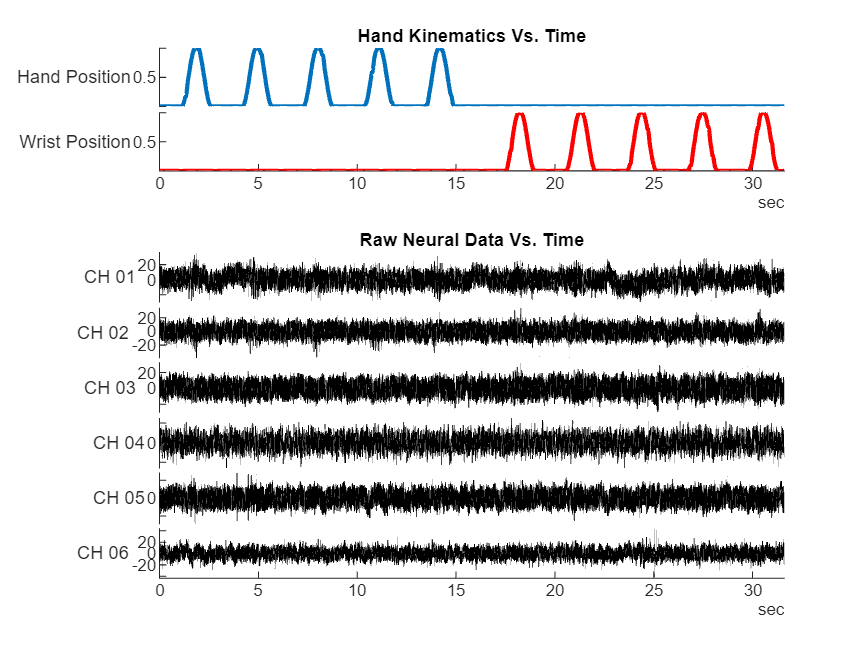

s_h.Color = "black";
end